%% 中值滤波法去除背景，无明场对比
close all
clear all
clc
tiffpath = 'D:\work\散射场\实验数据\20220408_PsNPs_colission\PsNPs_300nm\BG';
tiffs = dir(fullfile(tiffpath,'*.tiff'));

BG = MVMExtBG(tiffpath);

I = double(imread(fullfile(tiffpath,tiffs(1).name))) - BG;

figure
imagesc(I);
axis off
axis equal
colormap(sunglow)

F = fftshift(fft2(I));
[center_raw,center_col,R,~] = findcircle(log(abs(F)),5,0,1);
peaks = [center_col,center_raw,R];

mask = EwaldMask(F,peaks,0.15,'G',2);
I_rcn = abs(ifft2(ifftshift(F.*mask)));
figure
imagesc(I_rcn)
axis off
axis equal
colormap(sunglow)

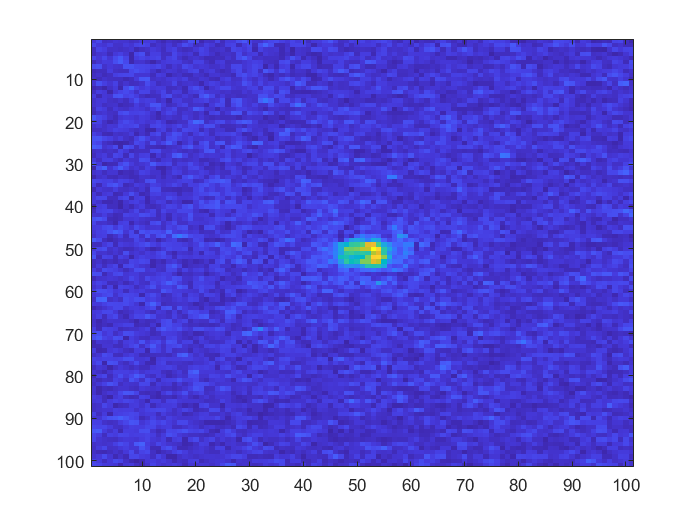

rect = [279 123 100 100];
I1 = imcrop(I_rcn,rect);
I2 = imcrop(I,rect);
[int_rcn,x,y] = LineCut(I1);
int_raw = LineCut(I2,x,y);

hl = findobj(gca,'type','line');
hl(2).XData = 1:length(int_raw);
hl(2).YData = int_raw;
hl(1).XData = 1:length(int_rcn);
hl(1).YData = 2*int_rcn;
xlim([1 93]);ylim([-500 5000])